t1=linspace(0,360,500)

t1 =          0    0.7214    1.4429    2.1643    2.8858    3.6072    4.3287    5.0501    5.7715    6.4930    7.2144    7.9359    8.6573    9.3788   10.1002   10.8216   11.5431   12.2645   12.9860   13.7074   14.4289   15.1503   15.8717   16.5932   17.3146   18.0361   18.7575   19.4790   20.2004   20.9218   21.6433   22.3647   23.0862   23.8076   24.5291   25.2505   25.9719   26.6934   27.4148   28.1363   28.8577   29.5792   30.3006   31.0220   31.7435   32.4649   33.1864   33.9078   34.6293   35.3507


t=(t1).*pi/180;
y=zeros(size(t));
for j=1:length(t)
    i=t(j);   
 if i>=0 && i<(pi/2)
    y(j)=6*((2.*i)-(0.5.*sin(i)))./pi;
 else if i>=pi/2 && i<(2*pi/3)
        y(j)=6;
 else if i>=(2*pi/3) && i<(4*pi/3)
        y(j)=6-3.*(1-0.5.*cos(3.*(i-(2*pi/3))));
 else if i>=(4*pi/3) && i<(3*pi/2)
         y(j)=6;
 else if i>=3*pi/2 && i<7*pi/4
        y(j)=3-1.5.*(((i-3).*(pi/2))/(pi/4))^2;
 else if  i>=7*pi/4 && i<=2*pi
        y(j) = 0.75-(0.75*(1-((i-7).*(pi/4))/(pi / 4))^2);
         
 end
end
end
end
 end
 end
end
disp(y)

  Columns 1 through 12

         0    0.0361    0.0721    0.1082    0.1443    0.1804    0.2165    0.2526    0.2887    0.3249    0.3610    0.3972

  Columns 13 through 24

    0.4334    0.4696    0.5059    0.5422    0.5785    0.6148    0.6511    0.6875    0.7240    0.7604    0.7970    0.8335

  Columns 25 through 36

    0.8701    0.9067    0.9434    0.9802    1.0170    1.0538    1.0907    1.1276    1.1646    1.2017    1.2388    1.2760

  Columns 37 through 48

    1.3133    1.3506    1.3880    1.4254    1.4630    1.5006    1.5382    1.5760    1.6138    1.6517    1.6897    1.7278

  Columns 49 through 60

    1.7660    1.8042    1.8425    1.8810    1.9195    1.9581    1.9968    2.0356    2.0745    2.1135    2.1525    2.1917

  Columns 61 through 72

    2.2310    2.2704    2.3099    2.3495    2.3892    2.4291    2.4690    2.5091    2.5492    2.5895    2.6299    2.6704

  Columns 73 through 84

    2.7110    2.7518    2.7926    2.8336    2.8747    2.9159    2.9573    2.9988    3.0404    

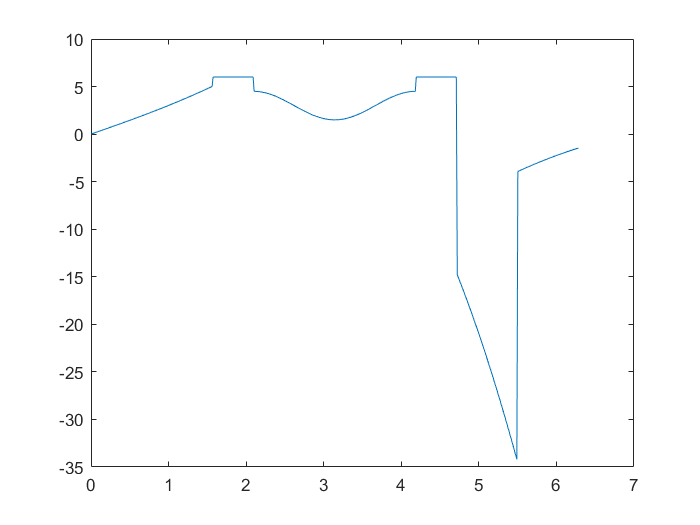

plot(t,y)